clear;

rgbImage = imread('CarrinaNebula_2k.jpg');

% Image Conversion

% RGB colorspace
rgbImageDBL = rescale(im2double(rgbImage));
[rImageDBL, gImageDBL, bImageDBL] = imsplit(rgbImageDBL);
% YCbCr colorspace
yCbCrImage = rgb2ycbcr(rgbImage);
[yImage, CbImage, CrImage] = imsplit(yCbCrImage);
YImageDBL  = im2double(yImage);
CbImageDBL = im2double(CbImage);
CrImageDBL = im2double(CrImage);

% Singular values
Sr = svd(rImageDBL);  Sg = svd(gImageDBL);   Sb = svd(bImageDBL);
Sy = svd(YImageDBL); SCb = svd(CbImageDBL); SCr = svd(CrImageDBL);

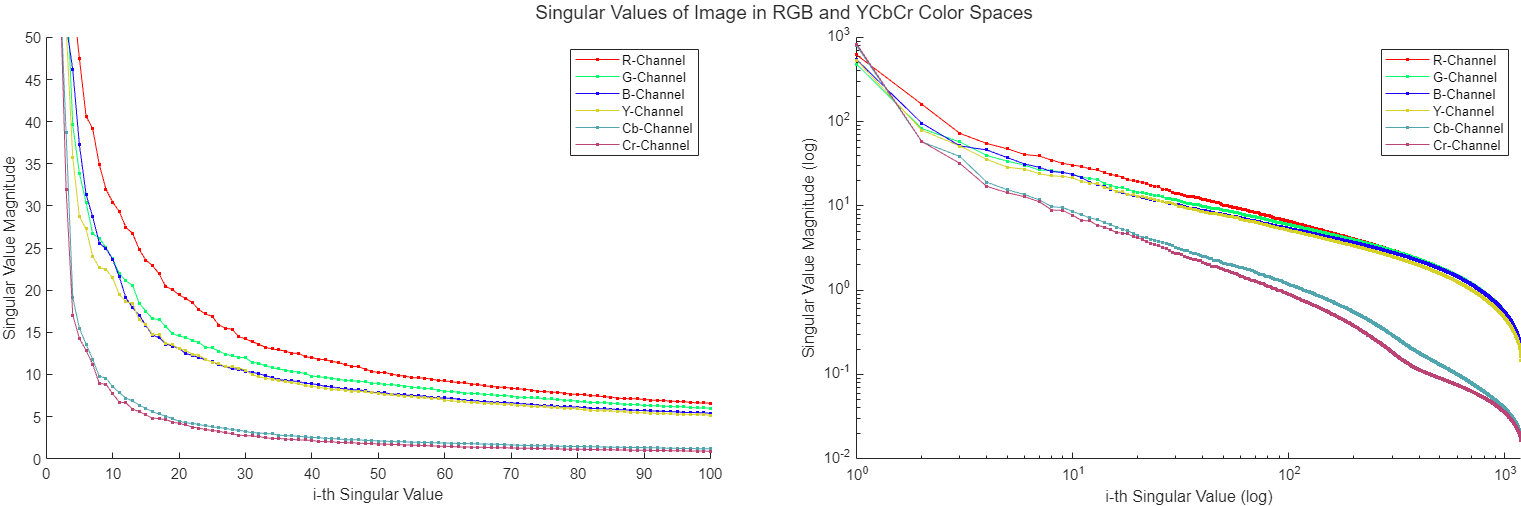

% Plot of singular values

xx = 1 : length(Sr);
t = tiledlayout(1, 2, 'Padding', 'tight');
title(t, "Singular Values of Image in RGB and YCbCr Color Spaces");

nexttile; % left plot
hold on;
axis([0 100 0 50]);
ylabel("Singular Value Magnitude");
xlabel("i-th Singular Value");
legend('Location', 'northeast');
plot(xx, Sr,  'Color', '#ff0700', 'LineStyle', '-', 'Marker', '.', ...
    'DisplayName', "R-Channel");
plot(xx, Sg,  'Color', '#00ff68', 'LineStyle', '-', 'Marker', '.', ...
    'DisplayName', "G-Channel");
plot(xx, Sb,  'Color', '#1b00ff', 'LineStyle', '-', 'Marker', '.', ...
    'DisplayName', "B-Channel");
plot(xx, Sy,  'Color', '#d6d129', 'LineStyle', '-', 'Marker', '.', ...
    'DisplayName', "Y-Channel");
plot(xx, SCb, 'Color', '#51a5ae', 'LineStyle', '-', 'Marker', '.', ...
    'DisplayName', "Cb-Channel");
plot(xx, SCr, 'Color', '#bb4474', 'LineStyle', '-', 'Marker', '.', ...
    'DisplayName', "Cr-Channel");
hold off;

nexttile; % right plot
hold on;
legend('Location', 'northeast');
yscale log; xscale log;
ylabel("Singular Value Magnitude (log)");
xlabel("i-th Singular Value (log)");
plot(xx, Sr,  'Color', '#ff0700', 'LineStyle', '-', 'Marker', '.', ...
    'DisplayName', "R-Channel");
plot(xx, Sg,  'Color', '#00ff68', 'LineStyle', '-', 'Marker', '.', ...
    'DisplayName', "G-Channel");
plot(xx, Sb,  'Color', '#1b00ff', 'LineStyle', '-', 'Marker', '.', ...
    'DisplayName', "B-Channel");
plot(xx, Sy,  'Color', '#d6d129', 'LineStyle', '-', 'Marker', '.', ...
    'DisplayName', "Y-Channel");
plot(xx, SCb, 'Color', '#51a5ae', 'LineStyle', '-', 'Marker', '.', ...
    'DisplayName', "Cb-Channel");
plot(xx, SCr, 'Color', '#bb4474', 'LineStyle', '-', 'Marker', '.', ...
    'DisplayName', "Cr-Channel");
hold off;

% Image Compression

k1 = 1000; k2 = 500; k3 = 250; k4 = 125; % compression parameters

% RGB Compression

% Test 1
[UR, BR, VR] = lrf(rImageDBL, k1, k1);
rImageDBL_LRF1 = UR*BR*VR';
[UG, BG, VG] = lrf(gImageDBL, k1, k1);
gImageDBL_LRF1 = UG*BG*VG';
[UB, BB, VB] = lrf(bImageDBL, k1, k1);
bImageDBL_LRF1 = UB*BB*VB';
compImageRGB1(:, :, 1) = rImageDBL_LRF1;
compImageRGB1(:, :, 2) = gImageDBL_LRF1;
compImageRGB1(:, :, 3) = bImageDBL_LRF1;

% Test 2
[UR, BR, VR] = lrf(rImageDBL, k2, k2);
rImageDBL_LRF2 = UR*BR*VR';
[UG, BG, VG] = lrf(gImageDBL, k2, k2);
gImageDBL_LRF2 = UG*BG*VG';
[UB, BB, VB] = lrf(bImageDBL, k2, k2);
bImageDBL_LRF2 = UB*BB*VB';
compImageRGB2(:, :, 1) = rImageDBL_LRF2;
compImageRGB2(:, :, 2) = gImageDBL_LRF2;
compImageRGB2(:, :, 3) = bImageDBL_LRF2;

% Test 3
[UR, BR, VR] = lrf(rImageDBL, k3, k3);
rImageDBL_LRF3 = UR*BR*VR';
[UG, BG, VG] = lrf(gImageDBL, k3, k3);
gImageDBL_LRF3 = UG*BG*VG';
[UB, BB, VB] = lrf(bImageDBL, k3, k3);
bImageDBL_LRF3 = UB*BB*VB';
compImageRGB3(:, :, 1) = rImageDBL_LRF3;
compImageRGB3(:, :, 2) = gImageDBL_LRF3;
compImageRGB3(:, :, 3) = bImageDBL_LRF3;

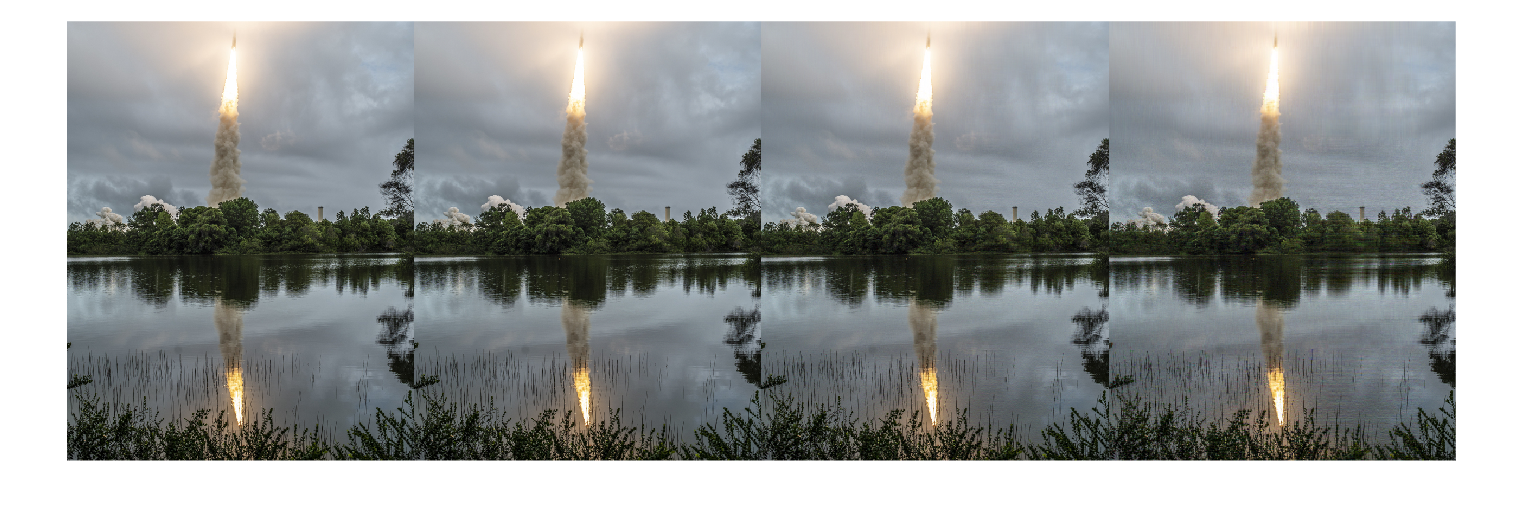

figure();
montage({rgbImage, compImageRGB1, compImageRGB2, compImageRGB3}, 'Size', [1, 4])

% yCbCr Compression

% Test 1
[UY, BY, VY] = lrf(YImageDBL, k1, k1);
YImageDBL_LRF1 = UY*BY*VY';
[UCb, BCb, VCb] = lrf(CbImageDBL, k3, k3);
CbImageDBL_LRF1 = UCb*BCb*VCb';
[UCr, BCr, VCr] = lrf(CrImageDBL, k3, k3);
CrImageDBL_LRF1 = UCr*BCr*VCr';
compImage1(:, :, 1) = YImageDBL_LRF1;
compImage1(:, :, 2) = CbImageDBL_LRF1;
compImage1(:, :, 3) = CrImageDBL_LRF1;
compImage1 = ycbcr2rgb(compImage1);

% Test 2
[UY, BY, VY] = lrf(YImageDBL, k2, k2);
YImageDBL_LRF2 = UY*BY*VY';
[UCb, BCb, VCb] = lrf(CbImageDBL, k2, k2);
CbImageDBL_LRF2 = UCb*BCb*VCb';
[UCr, BCr, VCr] = lrf(CrImageDBL, k2, k2);
CrImageDBL_LRF2 = UCr*BCr*VCr';
compImage2(:, :, 1) = YImageDBL_LRF2;
compImage2(:, :, 2) = CbImageDBL_LRF2;
compImage2(:, :, 3) = CrImageDBL_LRF2;
compImage2 = ycbcr2rgb(compImage2);

% Test 3
[UY, BY, VY] = lrf(YImageDBL, k3, k3);
YImageDBL_LRF3 = UY*BY*VY';
[UCb, BCb, VCb] = lrf(CbImageDBL, k3, k3);
CbImageDBL_LRF3 = UCb*BCb*VCb';
[UCr, BCr, VCr] = lrf(CrImageDBL, k3, k3);
CrImageDBL_LRF3 = UCr*BCr*VCr';
compImage3(:, :, 1) = YImageDBL_LRF3;
compImage3(:, :, 2) = CbImageDBL_LRF3;
compImage3(:, :, 3) = CrImageDBL_LRF3;
compImage3 = ycbcr2rgb(compImage3);

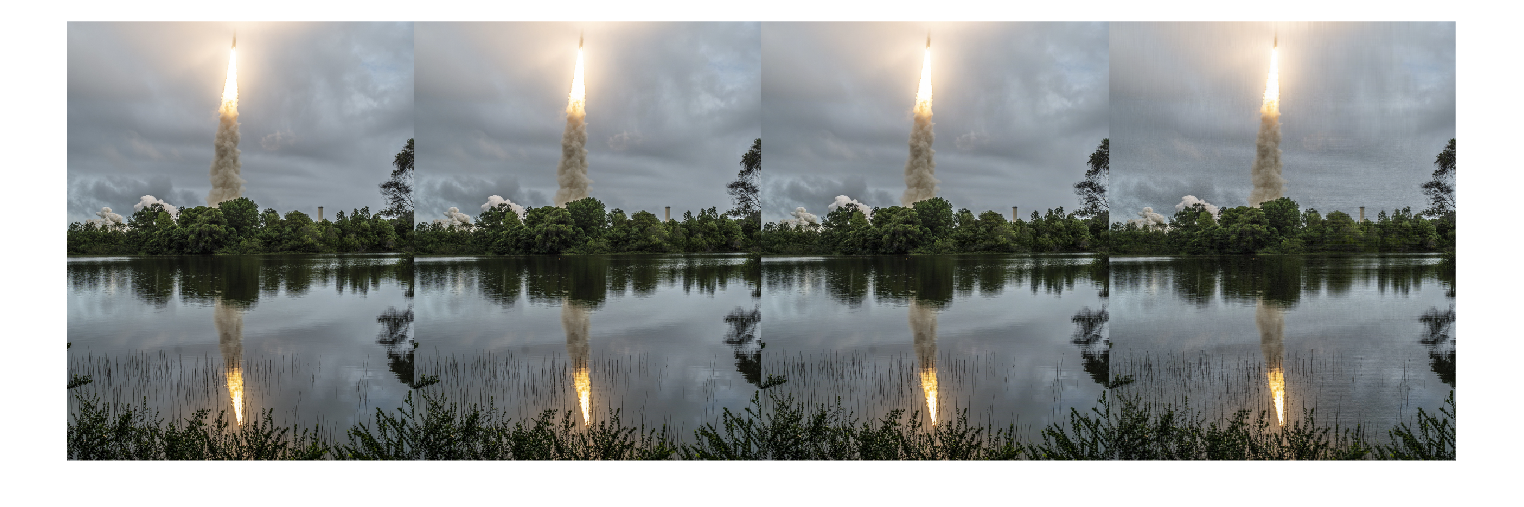

figure();
montage({rgbImage, compImage1, compImage2, compImage3}, 'Size', [1, 4])

ax = gca;
% export_fig jwst_launch_montage -png;

% Image metrics

err1 = immse(compImage1, rgbImageDBL); err2 = immse(compImage2, rgbImageDBL); err3 = immse(compImage3, rgbImageDBL);
psnr1 = psnr(compImage1, rgbImageDBL); psnr2 = psnr(compImage2, rgbImageDBL); psnr3 = psnr(compImage3, rgbImageDBL);
piqe0 = piqe(rgbImageDBL); piqe1 = piqe(compImage1); piqe2 = piqe(compImage2); piqe3 = piqe(compImage3);
niqe0 = niqe(rgbImageDBL); niqe1 = niqe(compImage1); niqe2 = niqe(compImage2); niqe3 = niqe(compImage3);
brisque0 = brisque(rgbImageDBL); brisque1 = brisque(compImage1); brisque2 = brisque(compImage2); brisque3 = brisque(compImage3);
ssim1 = ssim(compImage1, rgbImageDBL); ssim2 = ssim(compImage2, rgbImageDBL); ssim3 = ssim(compImage3, rgbImageDBL);

er = [0; err1; err2; err3];
ps = [0; psnr1; psnr2; psnr3];
ss = [0; ssim1; ssim2; ssim3];
br = [brisque0; brisque1; brisque2; brisque3];
nq = [niqe0; niqe1; niqe2; niqe3];
pq = [piqe0; piqe1; piqe2; piqe3];
T = table(er, ps, ss, br, nq, pq);

T = 4×6 table
        er          ps        ss         br        nq        pq  
    __________    ______    _______    ______    ______    ______

             0         0          0    25.343    1.7416    25.278
    4.7994e-05    43.188    0.98632    16.517    2.3973    22.871
    0.00049264    33.075    0.92108    12.444    3.0866    25.921
     0.0016061    27.942    0.83374    10.366     3.155    27.397
